%% MATLAB script to transfer acquired waveforms from Tektronix MSO5000 series oscilloscope 
% This example illustrates the use of MATLAB to set up a Tektronix
% MSO5000 series oscilloscope to acquire a waveform and then transfer the
% acquired waveform to MATLAB. Tektronix VISA will be used for
% communicating with your instrument, please ensure that it is installed.
%
% This script was tested with a Tek MSO5034
% 
% Copyright 2014 The MathWorks, Inc.
% Clear MATLAB workspace of any previous instrument connections
clear all; clc;

% Provide the Resource name of the oscilloscope - Note you will have to
% change this to match your oscilloscope.
visaAddress = "USB0::0x0699::0x0421::C026909::0::INSTR"; %"PXI0::MEMACC";%'USB0::0x0699::0x03C7::C020471::INSTR';%'USB0::0x0699::0x0401::C002176::0::INSTR';
% Create a VISA object and set the |InputBufferSize| to allow for transfer
% of waveform from oscilloscope to MATLAB. Tek VISA needs to be installed.
%myScope = visa('ni', visaAddress);

myScope = visa("ni", visaAddress);

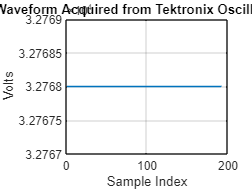

%myScope.write('*RST');
%myScope.write('*CLS');
%myScope.visastatus


myScope.InputBufferSize = 1024;
% Set the |ByteOrder| to match the requirement of the instrument
myScope.ByteOrder = 'littleEndian';
% Open the connection to the oscilloscope
fopen(myScope);
% Reset the oscilloscope to a known state
% myScope.write("TRIGger:EXTernal:PRObe 1");
% myScope.write('AUTOSet Execute');
% myScope.write('CH1:TERmination FIFty');
% myScope.write('CH2:TERmination FIFty');
% myScope.write('ACQuire:MODe AVErage');
% myScope.write('ACQuire:NUMAVg 256');
fprintf(myScope, "TRIGger:EXTernal:PRObe 1")
fprintf(myScope, "AUTOSet Execute")
fprintf(myScope, "CH1:TERmination FIFty")
fprintf(myScope, "CH2:TERmination FIFty")
fprintf(myScope, "ACQuire:MODe AVErage")
fprintf(myScope, "ACQuire:NUMAVg 256")

%myScope.flush("input");
%myScope.flush("output");

% Turn headers off, this makes parsing easier
%myScope.write('HEADER OFF');
fprintf(myScope,'HEADER OFF');

%myScope.write('MEASUrement:MEAS1:TYPe Amplitude');
%myScope.write('MEASUrement:MEAS2:TYPe Amplitude');

fprintf(myScope,'MEASUrement:MEAS1:TYPe Amplitude')
fprintf(myScope,'MEASUrement:MEAS2:TYPe Amplitude')

%myScope.query('MEASUrement:IMMed:UNIts?')

% myScope.write('MEASUrement:MEAS1:SOUrceCH1');
% myScope.write('MEASUrement:MEAS2:SOUrceCH2');

fprintf(myScope,'MEASUrement:MEAS1:SOUrceCH1')
fprintf(myScope,'MEASUrement:MEAS2:SOUrceCH2')
%query(myScope,'MEASUrement:MEAS1:SOUrce1?')
%query(myScope,'MEASUrement:MEAS2:SOUrce2?')

%fprintf(myScope,"DATA:SOUrce CH2")

% Autoset the oscilloscope 
%fprintf(myScope, 'AUTOS EXECute');
% Get record length value
%recordLength = query(myScope, 'HOR:RECO?')
recordLength = str2double(query(myScope,'HOR:RECO?'));
%recordLength = 10000;
fprintf(myScope,sprintf("HORizontal:RECOrdlength %d",recordLength))
%myScope.write("HORizontal:RECOrdlength:Auto 1");

%myScope.write("DATa:STARt 1");
%myScope.write("DATa:STOP 10000");

%recordLength

%myScope.write("ACQuire:STOPAFTER RUnSTOP");
fprintf(myScope,"ACQuire:STOPAFTER RUnSTOP");

% Ensure that the start and stop values for CURVE query match the full
% record length
fprintf(myScope, ['DATA:START 1;DATA:STOP ' recordLength]);
%myScope.write('')
% Read YOFFSET to calculate the vertical values
%yOffset = query(myScope, 'WFMO:YOFF?');
% Read YMULT to calculate the vertical values
%verticalScale  = query(myScope,'WFMOUTPRE:YMULT?')
% Request 8 bit binary data on the CURVE query
%myScope.write('DATA:ENCDG RIBINARY;WIDTH 2');
fprintf(myScope,'DATA:ENCDG RIBINARY;WIDTH 2');

%myScope.write("CLR*");
%myScope.visastatus

% Request the CURVE
query(myScope, 'CURVE?');
%myScope.writeread('CURVE?');
% Read the captured data as 8-bit integer data type
data = [];
for i = 1:12
    data_new = fread(myScope,16,"uint16");
    %data_new = str2double(verticalScale) * data_new + str2double(yOffset);
    data = [data; data_new];
end

%data = (str2double(verticalScale) * (binblockread(myScope,'int8')))' + str2double(yOffset);
% Clean up Close the connection
fclose(myScope);
% Clear the variable
clear myScope;
% Plot the acquired data and add axis labels
%scatter(1:length(data), data);
plot(data)
xlabel('Sample Index'); 
ylabel('Volts');
title('Waveform Acquired from Tektronix Oscilloscope');
grid on;